% Z:\01_Codes_Projects\git_fork_emach\tools\motorCAD\optislang\Paretoplot.m

deepNetworkDesigner


레이어 라이브러리에서 featureInputLayer를 캔버스로 드래그합니다.

레이어 라이브러리 필터를 사용하여 레이어를 찾을 수 있습니다. 

레이어를 선택합니다. 속성 창에서 정규화를 "zscore"로 설정하고 입력 크기를 데이터의 피처 수로 설정합니다. 

그런 다음, 완전히 연결된 레이어를 캔버스로 드래그합니다. 레이어를 연결하려면 featureInputLayer에서 일시 중지하고 out 포트를 클릭합니다. 화살표를 완전히 연결된 레이어의 in 포트로 드래그합니다. 

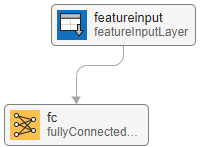

Add a `layerNormalizationLayer` followed by a `reluLayer` to the canvas and connect them sequentially. 

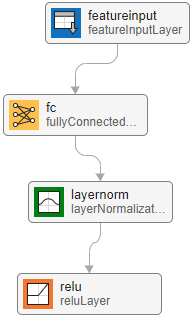

숫자 피처의 데이터 세트(예: 공간 또는 시간 차원이 없는 표 형식 데이터)가 있는 경우 피처 입력 레이어를 사용하여 심층 신경망을 훈련할 수 있습니다.

범주형 특징을 사용하여 네트워크를 훈련하려면 먼저 범주형 특징을 숫자로 변환해야 합니다. 먼저 모든 범주형 입력 변수의 이름이 포함된 문자열 배열을 지정하여 convertvars 함수를 사용하여 범주형 예측자를 범주로 변환합니다. 이 데이터 세트에는 "SensorCondition" 및 "ShaftCondition"이라는 이름의 범주형 특징이 두 개 있습니다.

범주형 입력 변수를 반복합니다. 각 변수에 대해 원핫코드 함수를 사용하여 범주형 값을 원핫 인코딩된 벡터로 변환합니다.

테이블의 처음 몇 행을 봅니다. 범주형 예측자가 여러 열로 분할되어 있음을 알 수 있습니다.

## CSV Import

sensitivityTable=readtable('Z:\Thesis\Optislang_Motorcad\HDEV_Code3\OPD\HDEV_ob2o24i28si1f1.py.opd\Samoo_HDEV_low_fidelity_sensitivity.csv');
sensitivityTable = removevars(sensitivityTable, "x_");
varNames = sensitivityTable.Properties.VariableNames;
labelName2 = varNames{end-1}
labelName ='o_Weight_Act'
% labelName = 'o_Maxtorque'
tbl =sensitivityTable;
 

## feature

범주형 특징을 사용하여 네트워크를 훈련하려면 먼저 범주형 특징을 숫자로 변환해야 합니다. 먼저 모든 범주형 입력 변수의 이름이 포함된 문자열 배열을 지정하여 convertvars 함수를 사용하여 범주형 예측자를 범주로 변환합니다. 이 데이터 세트에는 "SensorCondition" 및 "ShaftCondition"이라는 이름의 범주형 특징이 두 개 있습니다.

범주형 입력 변수를 반복합니다. 각 변수에 대해 원핫코드 함수를 사용하여 범주형 값을 원핫 인코딩된 벡터로 변환합니다.

테이블의 처음 몇 행을 봅니다. 범주형 예측자가 여러 열로 분할되어 있음을 알 수 있습니다.

## 2. 데이터셋 분할 (트레이닝, 검증)

테스트용 데이터를 따로 분리합니다. 데이터를 85%의 데이터를 포함하는 학습 세트와 나머지 15%의 데이터를 포함하는 테스트 세트로 분할합니다. 데이터를 분할하려면 이 예제에 지원 파일로 첨부된 trainingPartitions 함수를 사용합니다. 이 파일에 액세스하려면 예제를 라이브 스크립트로 엽니다.

numObservations = size(tbl,1);
[idxTrain,idxTest] = trainingPartitions(numObservations,[0.85 0.15]);

tblTrain = tbl(idxTrain,:);
tblTest = tbl(idxTest,:);

## 3. 데이터를 트레인넷 함수가 지원하는 형식으로 변환합니다. 

예측자(predictors)와 대상(targets)을 각각 숫자 배열과 범주 배열로 변환합니다. 

특징 입력(feature)의 경우, 네트워크는 관측값에 해당하는 행과 특징에 해당하는 열이 있는 데이터를 기대합니다. 데이터의 레이아웃이 다른 경우 이 레이아웃을 갖도록 데이터를 전처리하거나 데이터 형식을 사용하여 레이아웃 정보를 제공할 수 있습니다. 자세한 내용은[ 딥 러닝 데이터 형식](https://www.mathworks.com/help/releases/R2024a/deeplearning/ug/deep-learning-data-formats.html)을 참조하세요

predictorNamesCell = varNames(1:30);
predictorNames = string(predictorNamesCell);
responseName = labelName;

XTrain = table2array(tblTrain(:,predictorNames));
TTrain = tblTrain.(labelName);
TTrain2 = tblTrain.(labelName2);

XTest = table2array(tblTest(:,predictorNames));
TTest = tblTest.(labelName);
TTest2 = tblTest.(labelName2);

% 입력 및 출력 데이터 추출
XTrain = tblTrain{:, predictorNames};
YTrain = tblTrain{:, labelName};
YTrain2 = tblTrain{:, labelName2};

XTest = tblTest{:, predictorNames};
YTest = tblTest{:, labelName};
YTest2 = tblTest{:, labelName2};

## 딥러닝 데이터 형식

대부분의 딥러닝 네트워크와 함수는 서로 다른 방식으로 입력 데이터의 여러 차원에서 작동합니다.

예를 들어, LSTM 연산은 입력 데이터의 시간 차원을 반복하고, 배치 정규화 연산은 입력 데이터의 배치 차원을 정규화합니다.

데이터에는 여러 가지 유형의 레이아웃이 있을 수 있습니다.

- 데이터는 여러 차원을 가질 수 있습니다. 예를 들어, 이미지와 비디오 데이터를 각각 4차원과 5차원 배열로 표현할 수 있습니다.

- 데이터의 차원은 여러 가지를 나타낼 수 있습니다. 예를 들어, 이미지 데이터는 두 개의 공간 차원, 하나의 채널 차원, 하나의 배치 차원을 갖습니다.

- 데이터는 여러 순열의 차원을 가질 수 있습니다. 예를 들어, 시퀀스 배치는 채널, 시간 단계 및 관찰에 해당하는 차원을 가진 3차원 배열로 표현될 수 있습니다. 이러한 차원은 어떤 순서로든 될 수 있습니다.

소프트웨어가 올바른 차원에서 작동하는지 확인하려면 다양한 방법으로 데이터 레이아웃 정보를 제공할 수 있습니다.

*레이블이 지정된 차원을 입력 데이터에 제공하거나, 추가 레이아웃 정보를 입력 데이터에 제공하려면 데이터 형식을* 사용할 수 있습니다 .

데이터 형식은 문자열이며, 각 문자는 해당 데이터 차원의 유형을 설명합니다.

문자는 다음과 같습니다.

- `"S"`— 공간

- `"C"`— 채널

- `"B"`— 배치

- `"T"`- 시간

- `"U"`— 미지정

`"CBT"`예를 들어, 첫 번째, 두 번째, 세 번째 차원이 각각 채널, 관찰 및 시간 단계에 해당하는 시퀀스 배치를 포함하는 배열을 고려합니다. 이 배열이 (채널, 배치, 시간) 형식을 갖도록 지정할 수 있습니다.

## 4. Feature Input Layer 

#### 라벨 -  GearToothCondition

특징 입력 계층( a feature input layer )으로 네트워크를 정의하고 특징의 수(the number of features)를 지정합니다. - 현재는 category형

또한 Z-점수 정규화를 사용하여 데이터를 정규화하도록 입력 계층을 구성합니다.

numFeatures = size(XTrain,2);
% numClasses = numel(classNames);
% 모델 아키텍처 정의
% layers = [
%     featureInputLayer(numFeatures)
%     fullyConnectedLayer(64)
%     reluLayer
%     fullyConnectedLayer(32)
%     reluLayer
%     fullyConnectedLayer(1)
%     regressionLayer];
layers = [
    featureInputLayer(numFeatures)
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(1)
    ];

## 훈련 옵션을 지정합니다:

- L-BFGS 솔버를 사용해 훈련합니다. 이 솔버는 네트워크가 작고 데이터가 메모리에 맞는 작업에 적합합니다.  -> adam

- CPU를 사용하여 훈련. 네트워크와 데이터가 작기 때문에 CPU가 더 적합합니다.

                -> GPU

- 훈련 진행 상황을 플롯으로 표시합니다.

- 자세한 출력을 억제합니다.

% 학습 옵션 설정
options = trainingOptions('adam', ...
    'MaxEpochs', 200, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 1e-3, ...
    'Verbose', true, ...
    'Plots', 'training-progress', ...
    'Shuffle', 'every-epoch');


## 5. 트레인넷 함수를 사용해 네트워크를 훈련합니다. 

분류를 위해 교차 엔트로피 손실을 사용합니다.

## ->TraninNetwork Option > Loss Function

[https://kr.mathworks.com/help/releases/R2024a/deeplearning/ref/trainnet.html](https://kr.mathworks.com/help/releases/R2024a/deeplearning/ref/trainnet.html)

- `"mse"`

- `"mean-squared-error"`

- `"l2loss"`

- `"mae"`

- `"mean-absolute-error"`

- `"l1loss"`

- `"huber"`

% net = trainnet(XTrain,TTrain,layers,"mean-squared-error",options);
% net = trainNetwork(XTrain, YTrain, layers ,options);
net = trainnet(XTrain,YTrain,layers,"mean-squared-error",options);
net2 = trainnet(XTrain,YTrain2,layers,"mean-squared-error",options);


net.plot
net.layerGraph
net.activations(XTrain,1)

## GT - Prediction


% 예측값 계산
YPred = predict(net, XTest);
YPred2 = predict(net2, XTest);

YPred2 = predict(net, XTest);


% 실제값과 예측값 비교 그래프
figure;
plot(YTest, 'b-o'); hold on;
plot(YPred, 'r-*');
legend('Ground Truth', 'Prediction');
xlabel('Sample Index');
ylabel('Value');
title('Ground Truth vs Prediction');
grid on;

scatter(YTrain,YPred)
hold on
scatter(YTest,YPred2,'red')

scatter(YPred,YPred2,'red')
hold on
scatter(YTrain,YTrain2,'blue')
